# **Section 3: Image Restoration on Blurred License Plate (without noise)**

## Step - 1 Simulating Blurred Image

The blurred image is simulated using a Motion Filter

Read and displaying the original image before degradation process.

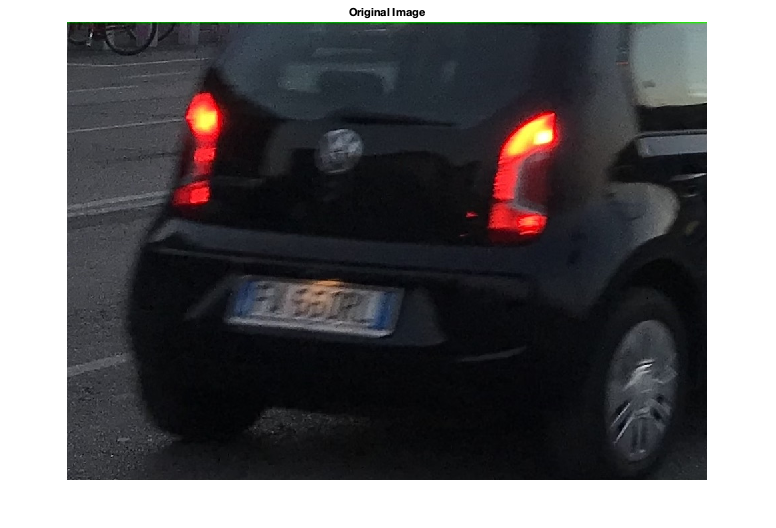

original_image = imread("data/cars_five_a.jpg");
imshow(original_image);
title('Original Image');

## Step 2 - Restoring The Image

Now we restore the degraded image using the Inverse Filter. In this situation we can restore the image using Inverse Filter, because the doesn't take into account the noise present in the degraded image.

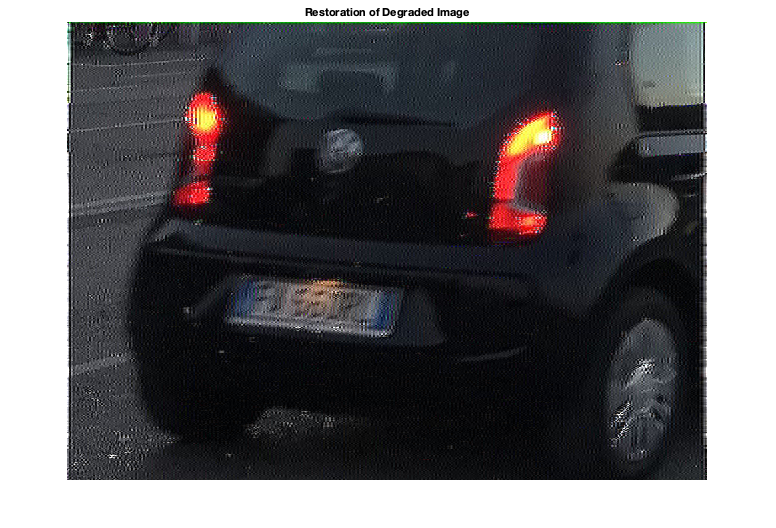

len = 2;
theta = -10;
original_image = im2double(original_image);
restored_image_Inverse = Inverse(original_image,len,theta);

imshow(restored_image_Inverse)
title('Restoration of Degraded Image');

Saving the restored image into a file.

imwrite(restored_image_Inverse,'data/cars_five_a_Inverse_len=2_theta=-10.jpg')

In this part we restore the degraded image using Wiener Filter.

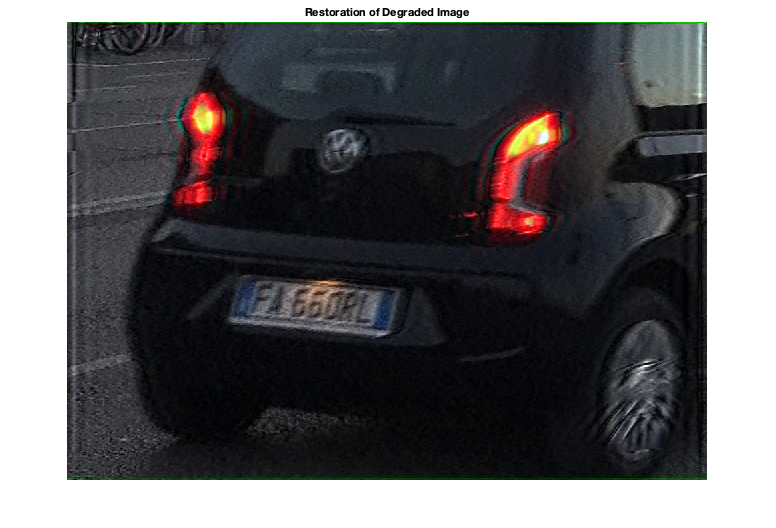

len = 21.3;
theta = 7.0;
SNR = 0.05;    % since there is no noise
restored_image_Wiener = Wiener_Filter(original_image,len,theta,SNR);
imshow(restored_image_Wiener)
title('Restoration of Degraded Image');

Saving the restored image into a file.

imwrite(restored_image_Wiener,'data/cars_five_a_Wiener_len=21.3_theta=7.3,SNR=0.05.jpg')